# KF test

## ovservation

$y_1$: upward distance measure

$y_2$: downward distance measure

## states

$x_1$: height of the drone

$x_2$: $-a_1$ displacement of roof, upward

$x_3$: $a_2$ displacement of terrain, downward

$x_4$: $-a_1'$

$x_5$: $a_2'$

## observation model


$$y_1 = H + 
\frac{x_2 + x_4}{2} 
- x_1+\epsilon_1,\ 
\epsilon_1 \sim \mathcal{N}(0,\sigma_1^2)$$



$$y_2 = x_1 - 
\frac{x_3 + x_5}{2}
 +\epsilon_2,\ 
\epsilon_2 \sim \mathcal{N}(0,\sigma_1^2)$$


## Transition model


$$x_{1,t} = x_{1,t-1} + u_1$$



$$x_{2,t} = a\cdot x_{2,t-1}
+ (1-a)x_{4,t-1}
+ u_2$$



$$x_{3,t} = a\cdot x_{3,t-1}
+ (1-a)x_{5,t-1}
+ u_3$$



$$x_4 = u_4$$



$$x_5 = u_5$$


## in other words


$$\left\lbrack \begin{array}{c}
x_{1,t} \\
x_{2,t} \\
x_{3,t} \\
x_{4,t} \\
x_{5,t} 
\end{array}\right\rbrack \sim N\left(\left\lbrack \begin{array}{c}
x_{1,t} \\
{a\cdot \;x}_{2,t} +\left(1-a\right)\cdot x_{4,t-1} \\
{a\cdot \;x}_{3,t} +\left(1-a\right)\cdot x_{5,t-1} \\
0\\
0
\end{array}\right\rbrack ,\mathrm{diag}\left(\left\lbrack \begin{array}{c}
\sigma_d^2 \\
\sigma_w^2 \\
\sigma_w^2 \\
\sigma_o^2 \\
\sigma_o^2 
\end{array}\right\rbrack \right)\right)$$



$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack \sim N\left(\left\lbrack \begin{array}{c}
H-x_1 +0\ldotp 5x_2 +0\ldotp 5x_4 \\
x_1 -0\ldotp 5x_3 -0\ldotp 5x_5 
\end{array}\right\rbrack ,\textrm{diag}\left(\left\lbrack \begin{array}{c}
\sigma_1^2 \\
\sigma_1^2 
\end{array}\right\rbrack \right)\right)$$


## in other words


$$Y=\left\lbrack \begin{array}{cccccc}
-1 & 0\ldotp 5 & 0 & 0\ldotp 5 & 0 & H\\
1 & 0 & -0\ldotp 5 & 0 & -0\ldotp 5 & 0
\end{array}\right\rbrack X+V$$



$$P=\textrm{diag}\left(\left\lbrack \begin{array}{c}
\sigma_1^2 \\
\sigma_1^2 
\end{array}\right\rbrack \right)$$



$$X_t =\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & a & 0 & 1-a & 0 & 0\\
0 & 0 & a & 0 & 1-a & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack X_{t-1} +U$$



$$Q=\mathrm{diag}\left(\left\lbrack \begin{array}{c}
\sigma_d^2 \\
\sigma_w^2 \\
\sigma_w^2 \\
\sigma_o^2 \\
\sigma_o^2 
\end{array}\right\rbrack \right)$$


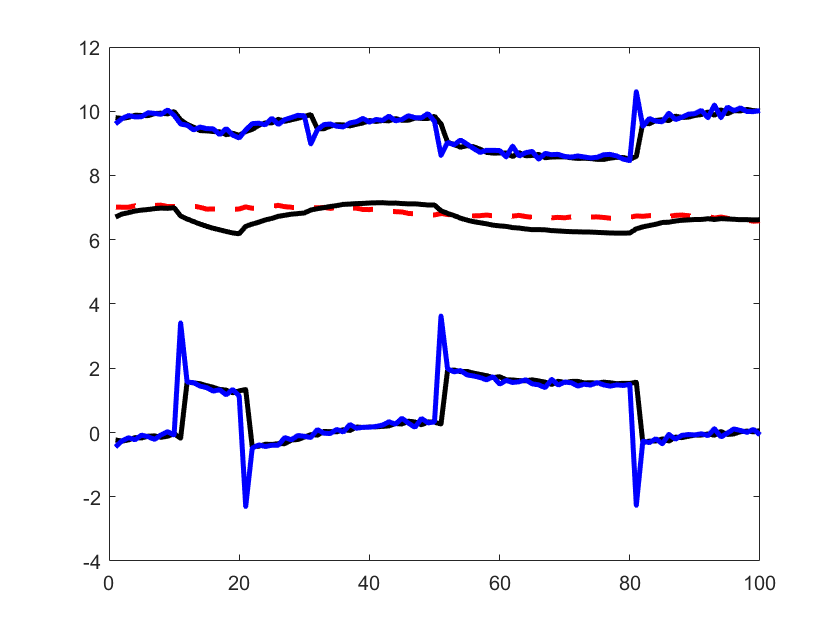

clear
close all
clc
addpath(genpath('..\..'))%% reach the functions and filters
load('height_est_simple_model_1.mat');
y_bad = y_bad([2,1],:);

alpha = 0.5;
beta = 0.5;
H = 10;
sig_y = 0.1;
sig_d = 0.1;
sig_w = 0.1;
sig_o = 1;

A = zeros(6,6);
A(1,1) = 1;
A(2,2) = alpha;
A(2,4) = 1 - alpha;
A(3,3) = alpha;
A(3,5) = 1 - alpha;
A(6,6) = 1;
C = [-1, beta, 0, (1-beta), 0, H;
    1, 0, -beta, 0, -(1-beta), 0];
R = diag([sig_y^2, sig_y^2]);
Q = diag([sig_d^2, sig_w^2, sig_w^2, sig_o^2, sig_o^2, 0]);

P_init = diag([1, 1, 1, 1, 1, 0]);
x_init = [5, 0, 0, 0, 0, 1]';

% Run the KF with bad measurements
x_est = kalman_filter_ye_ly(y_bad,A,C,Q,R,x_init,P_init);
% Plot inference with perfect measurements
figure()
plot(1:T,x,'--r','LineWidth',2.5); hold on;
plot(1:T,x_est(1,:),'-k','LineWidth',2.5); 
plot(1:T,H + x_est(2,:),'-k','LineWidth',2.5); 
plot(1:T,x_est(3,:),'-k','LineWidth',2.5); 
plot(1:T,H + x_est(4,:),'-b','LineWidth',2.5); 
plot(1:T,x_est(5,:),'-b','LineWidth',2.5); 
hold off;